Key topics that we'll review in this live script are:

- Rotation matrix

- Construct a Direction Cosine Matrix (DCM) from a given rotation sequence

- relationship between body rates and Euler rates 

- Understand the presense of singularity poses for a given sequense

# **PASSIVE** rotations and **EULER rates**

- **Rotations don't commute: **for example rotations involving a YAW, PITCH and ROLL of 90,30 60 degrees result in a different pose if the the sequence was in the order of RPY (reverse)

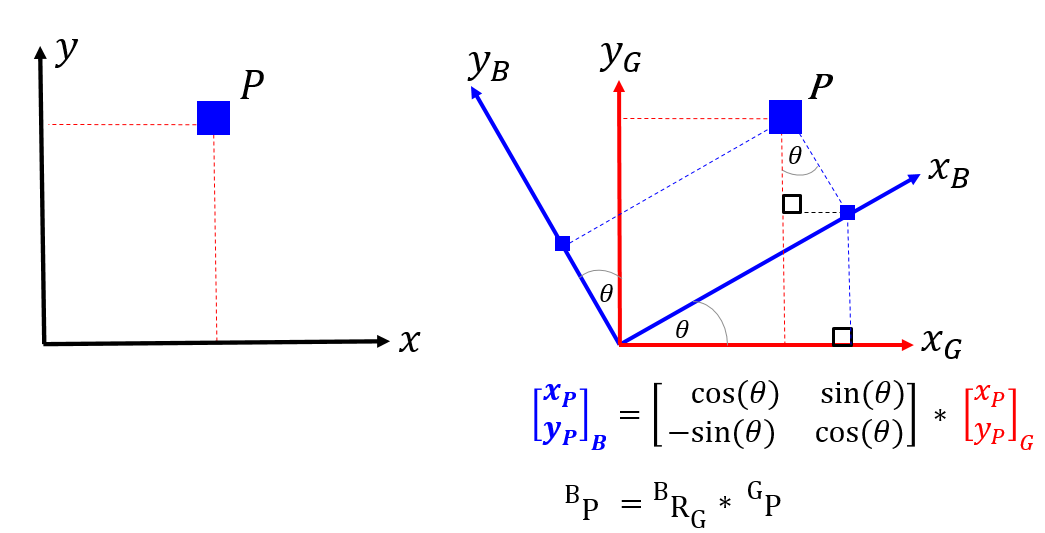 

A **PASSIVE** rotation matrix, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

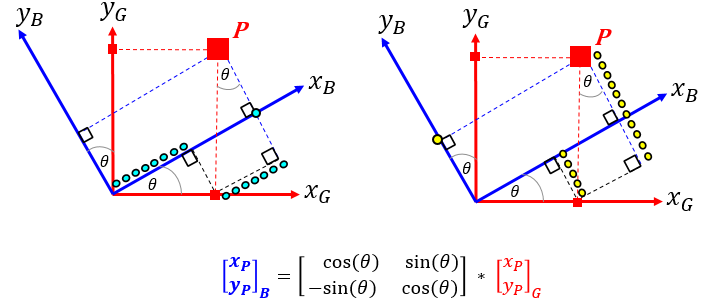

Another insight into the format of the $^BR_G$ Direction Cosine Matrix (DCM) is that it contains the projections(or components) of the  **G-frame** unit vectors onto the **B-frame**, ie:

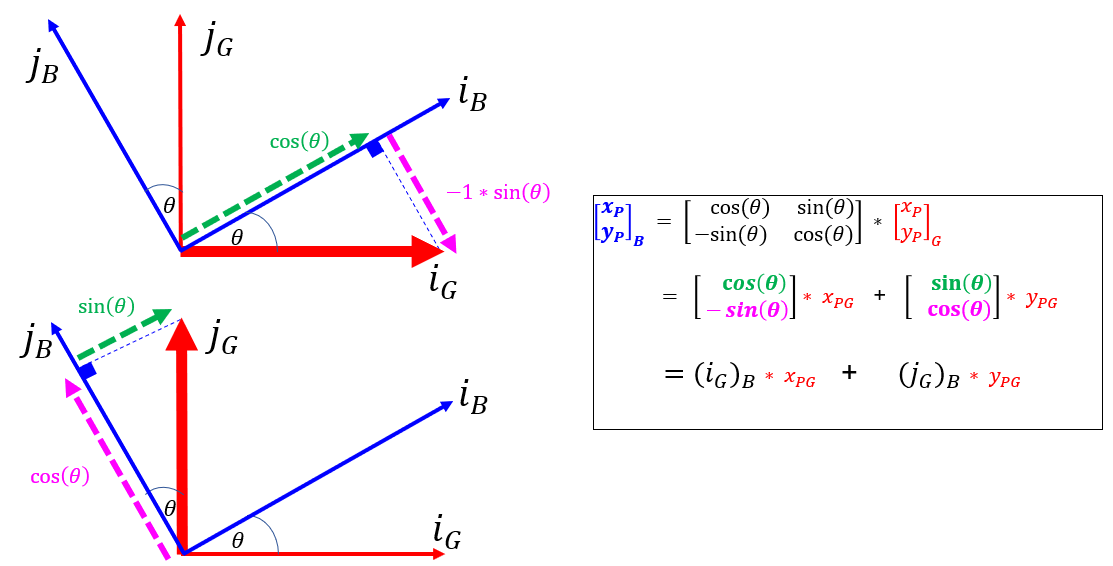

## An example of 3 successive PASSIVE rotations

Say we have a fixed G-frame. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 3 LOCAL axes rotations which will result in a newly orientated B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:


$$\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$$


    OR, in a more compact form as:


$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


## Passive rotation matrix

syms phi theta psi
R1Z = [  cos(phi),  sin(phi),  0;
        -sin(phi),  cos(phi),  0;
                 0,       0,  1;
         ]

$$R1Z = \left(\begin{array}{ccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0\\ -\sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2Y = [  cos(theta),      0,   -sin(theta);
             0,      1,         0;
        sin(theta),      0,    cos(theta);
     ]

$$R2Y = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

R3X = [       1,          0,         0;
             0,     cos(psi),    sin(psi);
             0,    -sin(psi),    cos(psi);
     ]

$$R3X = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## Calculate the Direction Cosine Matrix  ${^{B}}R_G $

Recall we earlier said:          $^{B}v  = {^{B}}R_G *  {^{G}}v$

bRg = R3X * R2Y * R1Z

$$bRg = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

## Explore the relationship between BODY rates and EULER rates

As we apply these local frame rotations of ($\phi, \theta, \psi$), we can represent the **angular rates** ($\dot{\phi}, \dot{\theta}, \dot{\matrix{\psi}}$) of the rotating frames into the LOCAL frame co-ordinates. These local frame co-ordinates can then be converted into co-ordinates expressed in the final B frame.  For example, during each of the local axes rotations we can think of there being a START frame and an END frame:

      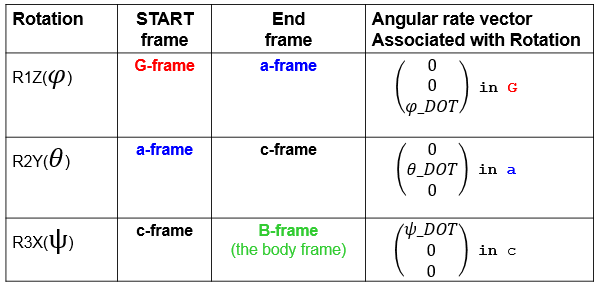

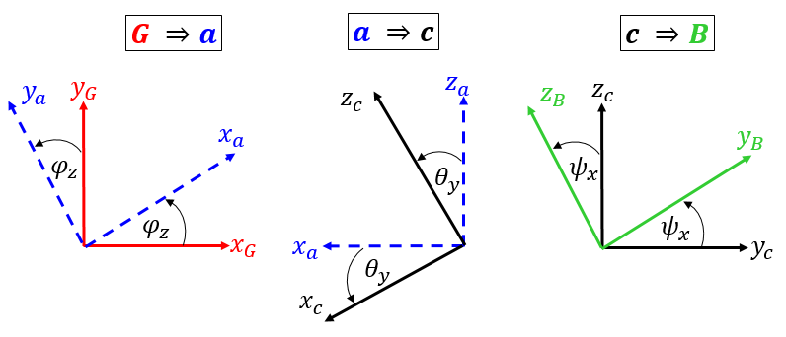

We can express each of the local frame angular velocities into their corresponding components in the final B frame - and we'll use PASSIVE rotation matrices to do this:

syms phi_dot  theta_dot  psi_dot

aRg = R1Z;
cRa = R2Y;
bRc = R3X;

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\phi}}$ rate:

wb_part_1 = bRc * cRa * aRg * [0;0;phi_dot]   % convert local G into B

$$wb\_part\_1 = \left(\begin{array}{c} -\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\varphi }\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \dot{\varphi }\,\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\theta}}$ rate:

wb_part_2 = bRc * cRa *       [0;theta_dot;0] % convert local a into B

$$wb\_part\_2 = \left(\begin{array}{c} 0\\ \dot{\theta }\,\cos\left(\psi \right)\\ -\dot{\theta }\,\sin\left(\psi \right) \end{array}\right)$$

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\psi}}$ rate:

wb_part_3 = bRc *             [psi_dot;0;0]   % convert local c into B

$$wb\_part\_3 = \left(\begin{array}{c} \dot{\psi }\\ 0\\ 0 \end{array}\right)$$

## The total angular velocity expressed in the BODY B frame is therefore

We can now construct the total angular velocity vector expressed in components of the final B frame.


$$_G^{B}\omega_b \equiv \omega_b = f( \dot{ \matrix{\phi}}, \dot{ \matrix{\theta}}, \dot{ \matrix{\psi}}, \phi, \theta, \psi) $$
 

wb = wb_part_1 + wb_part_2 + wb_part_3

$$wb = \left(\begin{array}{c} \dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\theta }\,\cos\left(\psi \right)+\dot{\varphi }\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \dot{\varphi }\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\dot{\theta }\,\sin\left(\psi \right) \end{array}\right)$$

## We can write the angular velocity vector $\omega_b$ as a MATRIX equation

Let's say that:  $ \omega_b = \pmatrix{p \cr q \cr r}
$, we can write a matrix equation of the form **A.x = b** that describes the relationship between the body rates $\omega_b$ and the Euler rates:  $A \times   \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  =  \pmatrix{p \cr q \cr r}  $  

syms p q r

x = [phi_dot, theta_dot, psi_dot].';
    
[A,b] = equationsToMatrix(  wb(1)==p, ...
                            wb(2)==q, ...
                            wb(3)==r, ...
                            x);
 

Just to clarify this, let me put each of the 3 elements side by side as  [**A, x, b] ,** where:


$$\matrix{
A & \times & x & = & b \cr
\downarrow & & \downarrow & & \downarrow \cr
A & \times & \pmatrix{\dot{\matrix{\phi}} \cr \dot{\matrix{\theta}}  \cr \dot{\matrix{\psi}}  } & = & \pmatrix{ ^B\omega_x \cr ^B\omega_y \cr ^B\omega_z} 

}$$


[A, x, b]                       

$$ans = \left(\begin{array}{ccccc} -\sin\left(\theta \right) & 0 & 1 & \dot{\varphi } & p\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right) & 0 & \dot{\theta } & q\\ \cos\left(\psi \right)\,\cos\left(\theta \right) & -\sin\left(\psi \right) & 0 & \dot{\psi } & r \end{array}\right)$$

## **ATTENTION:   The SINGULARITY between BODY rates and EULER rates**

From the Matrix equation computed above there is actually an angle that causes the determinant of **A** to be ZERO, and hence prevents us from solving for the Euler rates (at that angle) if we know the body rates $\omega_b$.  The angle that causes this problem is the rotation about the local Y axis, ie: the angle $\theta$. Specifically it is when $\theta = 90^o$.  We can see this by first computing the determinant of *A .*

det_A = simplify( det(A) )

$$det\_A = -\cos\left(\theta \right)$$

And then solving for its roots. 

[bad_theta, param_s, cond_s] = solve( det_A ==0, theta, 'ReturnConditions', true ) 

$$bad\_theta = \frac{\pi }{2}+\pi \,k$$

$$param\_s = k$$

$$cond\_s = k\in \mathbb{Z}$$

So this tells us that as soon as our vehicle has a pitch angle of  $\theta = 90^o$, that our chosen Euler angle sequence simply canNOT be used to convert FROM body rates $\omega_b$ TO  Euler rates.  So?  So, if you think your vehicle will pitch by $\theta = 90^o$ ... ***AND you're wanting to calculate EULER rates from body rates*** .... then you'll need to consider an alternate form of describing your vehicle's pose (eg: quaternions, or integrating directly the DCM) 

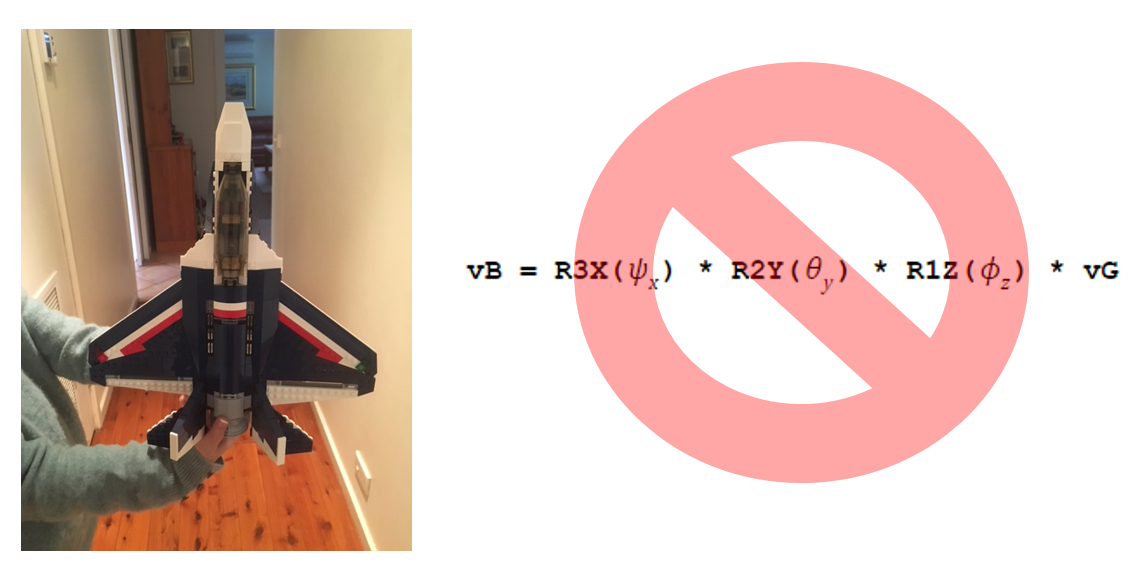

## Let's compute Euler rates from our body rates $\omega_b$

Assuming our vehicle does NOT have a pitch angle of $\theta = 90^o$, then we can use the results of the previous section to calculate the Euler rates from our body rates $\omega_b$.

      $\pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  = A^{-1} * \omega_b$       where      $ \omega_b = \pmatrix{p \cr q \cr r}
$

euler_rates = A \ [p; q; r];
euler_rates = simplify(euler_rates)                    

$$euler\_rates = \left(\begin{array}{c} \frac{r\,\cos\left(\psi \right)+q\,\sin\left(\psi \right)}{\cos\left(\theta \right)}\\ q\,\cos\left(\psi \right)-r\,\sin\left(\psi \right)\\ \frac{p\,\cos\left(\theta \right)+r\,\cos\left(\psi \right)\,\sin\left(\theta \right)+q\,\sin\left(\psi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} \end{array}\right)$$

## Create a REusable function from this expresion:

We can automatically convert these derived "symbolic" expressions into either MATLAB functions OR Simulink blocks(as a MATLAB Function block). So let's look at the following specific example:

- our relationship for converting FROM our body rates $^B\omega$ to our EULER rates

FILENAME        = 'bh_autogen_euler_rates';
INPUT_VAR_ORDER = {'theta', 'psi', 'p', 'q', 'r'};

Here is a MATLAB function:

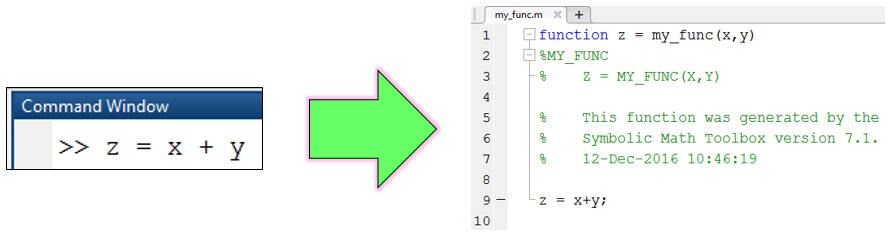

matlabFunction(euler_rates,'File',FILENAME, ...
              'Optimize',false, 'Vars', INPUT_VAR_ORDER);

% look at the autogenerated file
dbtype(FILENAME)   

1     function euler_rates = bh_autogen_euler_rates(theta,psi,p,q,r)
2     %BH_AUTOGEN_EULER_RATES
3     %    EULER_RATES = BH_AUTOGEN_EULER_RATES(THETA,PSI,P,Q,R)
4     
5     %    This function was generated by the Symbolic Math Toolbox version 8.7.
6     %    01-Dec-2022 16:39:53
7     
8     euler_rates = [(r.*cos(psi)+q.*sin(psi))./cos(theta);q.*cos(psi)-r.*sin(psi);(p.*cos(theta)+r.*cos(psi).*sin(theta)+q.*sin(psi).*sin(theta))./cos(theta)];


## Create a REusable Simulink Block from this expresion:

Here is the Simulink Block:

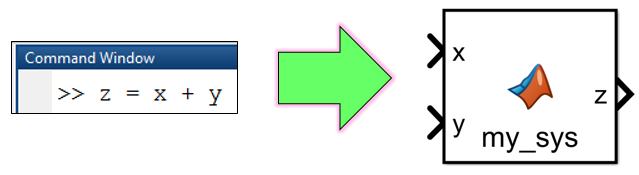

FILENAME        = 'SIM_bh_autogen_bRg';
BLOCK_NAME      = [FILENAME,'/my_euler_rates'];
new_system(FILENAME)
open_system(FILENAME)

matlabFunctionBlock(BLOCK_NAME, euler_rates, ...
                    'Optimize',false, 'Vars', INPUT_VAR_ORDER);
                    
BLOCK_NAME      = [FILENAME,'/bRg'];  
INPUT_VAR_ORDER = {'phi','theta','psi'};
matlabFunctionBlock(BLOCK_NAME, bRg, ...
                    'Optimize',false, 'Vars', INPUT_VAR_ORDER);